# **Week 5 : Optical Channel with BPSK**

The code below implements a preliminary model of an optical channel without DSPs and aims to investigate the feasibility of the model and the variation of the bit error rate (BER) with the signal-to-noise ratio (SNR)

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using BPSK

- A pulse shaper which creates an electrical signal using the generated symbols

- An IQ modulator which modulates the output of a laser according to an electrical signal

### Modulation

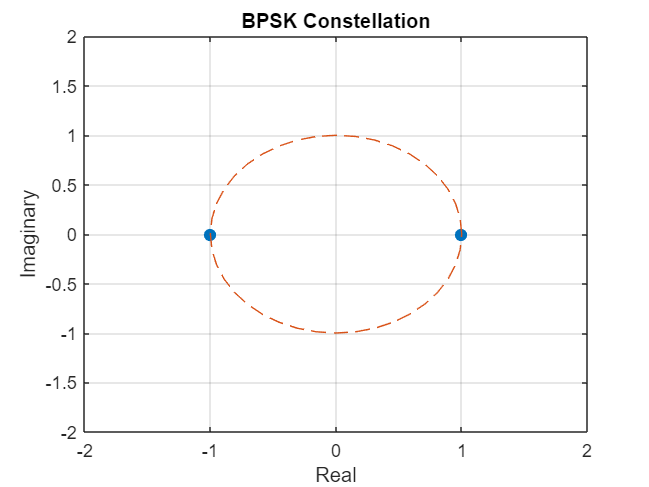

k = 1

symbols =    1.0000 + 0.0000i  -1.0000 + 0.0000i


clear all; clearvars;

% Modulation parameters
M = 2; % Modulation order

% Visualising constellation
[k, symbols] = PlotConstellation(M, 0)


% Generating random bit sequence(s)
NSymb = 500000; % No. of symbols 
SpS = 2; % Samples per symbol
Rs = 50e9; % Symbol rate in symbols/sec
NSequences = 15; % No. of bit sequences

sourceBits = randi([0 1], NSymb*k, NSequences); % Matrix of source bits
sourceSymbols = pskmod(sourceBits, M) % Maps source bit vector to symbol vector

sourceSymbols =    1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i
  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 

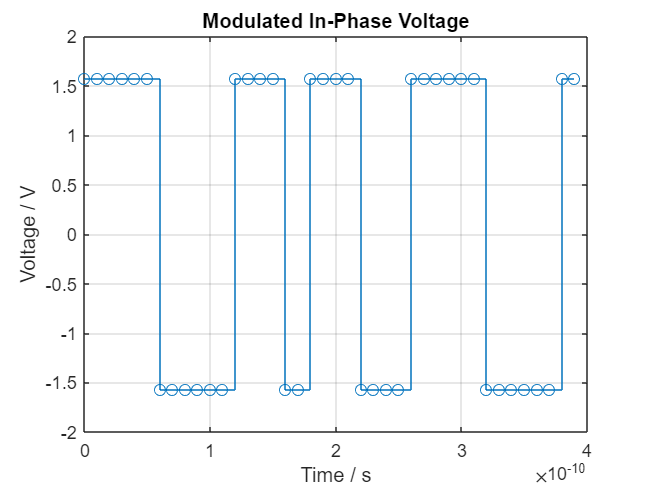


% bpskmod mapping: 0 -> 1+0i and 1 -> -1+0i

T = 1/(SpS*Rs); % Sampling period in s
t= [0:1:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

% Modulating voltage with generated symbols
DCOffset = 0; % DC offset of modulated current in V
Vmax = 1; % Sets the maximum value of the voltage
voltageLevels = [-pi/2, pi/2]';
realVals = [1 -1]'; % Storing the unique real values in the symbol constellation

vI = ones(size(sourceSymbols));
vQ = zeros(size(sourceSymbols)); % Quadrature voltage not significant as all symbols in BPSK have same imag. component

% Mapping the distinct real & imaginary values to their respective voltage levels
vI(real(sourceSymbols)>0) = voltageLevels(2); % Maps 1 -> pi/2
vI(real(sourceSymbols)<0) = voltageLevels(1); % Maps -1 -pi/2

vIupsampled = repelem(vI, SpS, 1); % Upsampling the voltage waveform based on SpS
vQupsampled = repelem(vQ, SpS, 1); % Upsampling the voltage waveform based on SpS

% Visualising in-phase and quadrature voltages
stairs(t(1:20*SpS), vIupsampled(1:20*SpS,1), "o-");
title("Modulated In-Phase Voltage")
xlabel("Time / s")
ylabel("Voltage / V")
grid on

### Adding AWGN

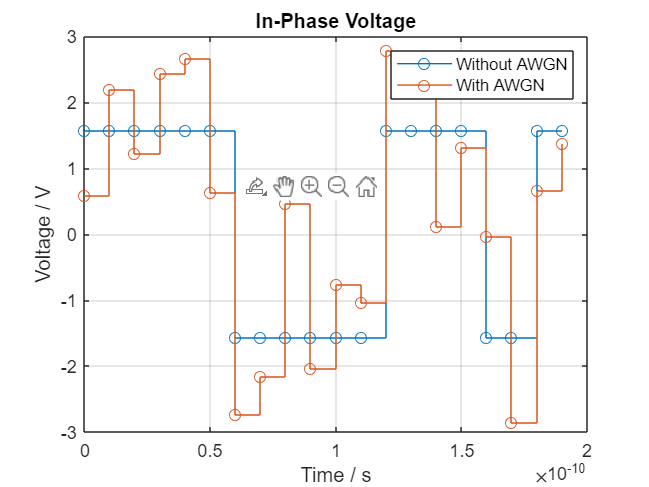

% Adding AWGN to the voltage waveforms before pulse shaping

SNRb_dB = [0:NSequences-1]'; % SNR per bit in dB
powerPerSymb = mean(voltageLevels.^2);
powerPerBit= powerPerSymb/k;

vUpsampled_AWGN = zeros(size(vIupsampled)); % Noisy signal to be continued without shaping
v_AWGN = zeros(size(vI)); % Noisy signal to be shaped 
for i=1:NSequences
    SNRb_Lin(i,1) = 10^(SNRb_dB(i,1)/10); % linear SNR per symbol
    AWGN_StdDev(i,1) = sqrt(powerPerBit/SNRb_Lin(i,1)); % AWGN Standard deviation
    v_AWGN(:,i) = (vI(:,i)+1i*vQ(:,i)) + (1/sqrt(2))*(AWGN_StdDev(i,1)*randn(size(v_AWGN,1),1) + 1i*AWGN_StdDev(i,1)*randn(size(v_AWGN,1),1));
    vUpsampled_AWGN(:,i) = (vIupsampled(:,i)+1i*vQupsampled(:,i)) + + (1/sqrt(2))*(AWGN_StdDev(i,1)*randn(size(vUpsampled_AWGN,1),1) + 1i*AWGN_StdDev(i,1)*randn(size(vUpsampled_AWGN,1),1));
end

% Debugging AWGN addition
% Visualising in-phase voltage with and without noise
stairs(t(1:10*SpS), vIupsampled(1:10*SpS,1), '-o');
hold on
stairs(t(1:10*SpS), real(vUpsampled_AWGN(1:10*SpS,1)), '-o');
title("In-Phase Voltage");
xlabel("Time / s");
ylabel("Voltage / V");
legend("Without AWGN", "With AWGN");
grid on
hold off

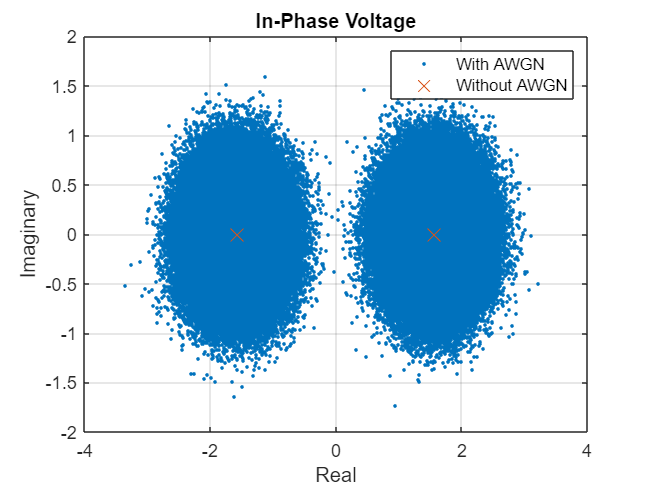


% Visualising symbol distribution with and without noise 
plot(v_AWGN(:,11), '.');
hold on
plot(vI(:,11), vQ(:,11), 'X', MarkerSize=10);
title("In-Phase Voltage");
xlabel("Real");
ylabel("Imaginary");
legend("With AWGN", "Without AWGN");
grid on
hold off


% Premature decoding to check validity of AWGN model
% tempInts = pskdemod(vUpsampled_AWGN, M);
% tempBits = int2bit(tempInts, k);
% 
% for i=1:NSequences
%     [~, tempBER(i,1)] = biterr(sourceBits(:,i), downsample(tempBits(:,i), SpS));
% end
% 
% % Visualising BER vs SNR plot
% semilogy(SNRb_dB(1:11), 0.5*erfc(sqrt(10.^(SNRb_dB(1:11)/10))));
% hold on
% semilogy(SNRb_dB, tempBER, "-o");
% title("BER vs SNR");
% xlabel("SNR per bit / dB");
% ylabel("BER");
% legend("Theoretical", "Simulation")
% grid on
% hold off



### Pulse Shaping

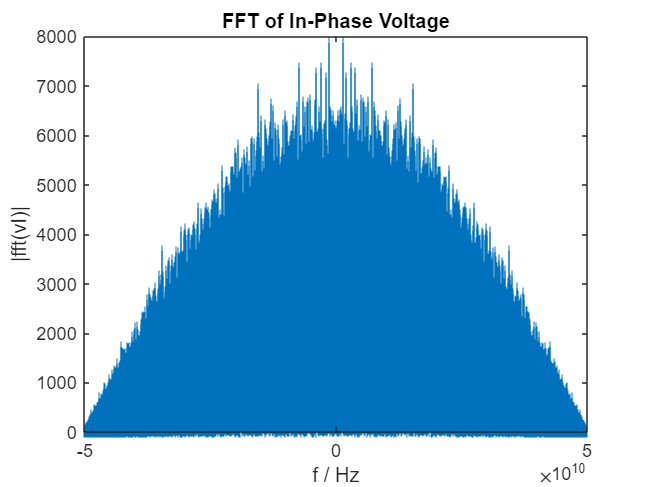

% Frequency spectrum of voltage waveform before filtering
fft_vI = fftshift(fft(vIupsampled(:,11))); % FFT without AWGN
freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);
stem(freqArr, abs(fft_vI), "|");
title("FFT of In-Phase Voltage");
xlabel("f / Hz");
ylabel("|fft(vI)|");

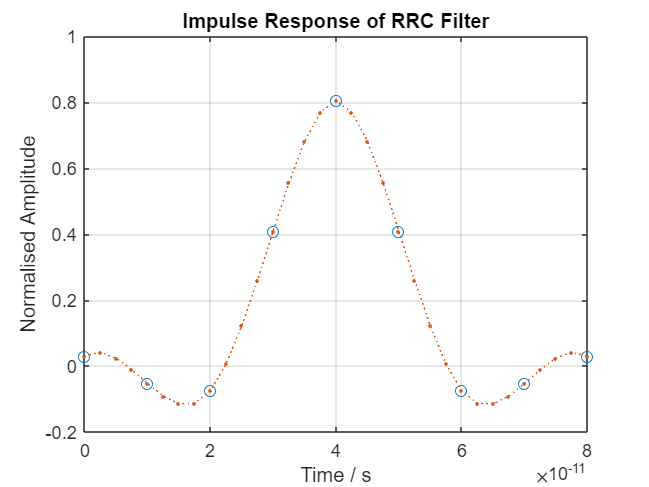


% RRC filter
filterSpan = 4; % Span of RRC filter in no. of symbols
rollOff = 0.5;
filterResponse = rcosdesign(rollOff, filterSpan, SpS)';

% Visualisation of RRC filter
filterResponse_t = [0:1:filterSpan*SpS]*T; % time vector for the filter response
filterResponse_t_interp = [0:0.25:filterSpan*SpS]*T;
filterResponse_interp = interp1(filterResponse_t, filterResponse, filterResponse_t_interp, "spline");
plot(filterResponse_t, filterResponse, "o", filterResponse_t_interp, filterResponse_interp, ":.");
title('Impulse Response of RRC Filter');
xlabel('Time / s');
ylabel('Normalised Amplitude');
grid on

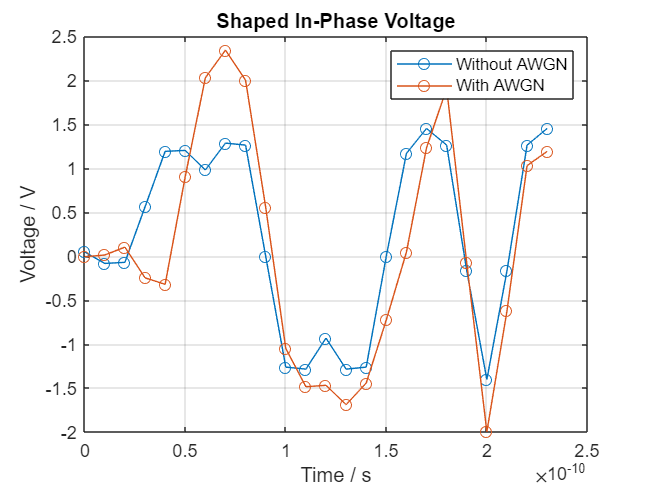


% Using RC filter to shape vI and vQ
% Without AWGN
vI_shaped = upfirdn(vI, filterResponse, SpS, 1); vQ_shaped = upfirdn(vQ, filterResponse, SpS, 1);
% With AWGN
vI_shaped_AWGN = upfirdn(real(v_AWGN), filterResponse, SpS, 1); vQ_shaped_AWGN = upfirdn(imag(v_AWGN), filterResponse, SpS, 1);


% Visualising pulse-shaped voltages
samples = 1+(NSymb-1)*SpS + filterSpan*SpS;
v_shaped_t = [0:1:samples-1]*T;
plot(v_shaped_t(1:10*SpS + filterSpan), vI_shaped(1:10*SpS + filterSpan,1), "o-");
hold on
plot(v_shaped_t(1:10*SpS + filterSpan), real(vI_shaped_AWGN(1:10*SpS + filterSpan,1)), "o-");
title("Shaped In-Phase Voltage");
ylabel("Voltage / V");
xlabel('Time / s');
legend("Without AWGN", "With AWGN");
grid on
hold off

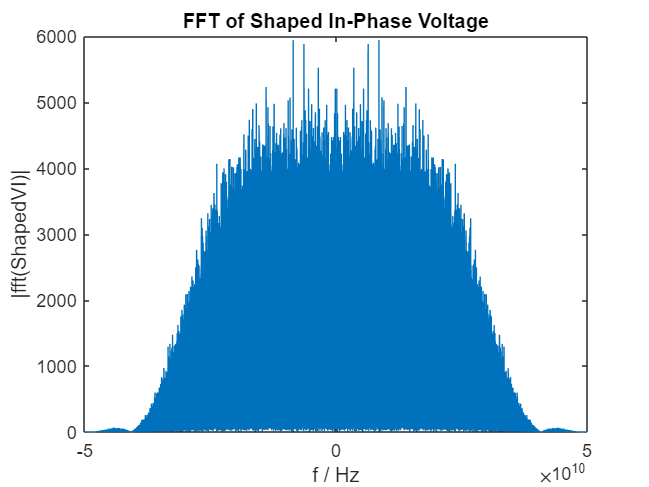

% Frequency spectrum of voltage waveform after filtering
fft_vI_shaped = fftshift(fft(vI_shaped(:,1)));
freqArr = [-samples/2:samples/2 - 1]/(T*samples);
plot(freqArr, abs(fft_vI_shaped));
title("FFT of Shaped In-Phase Voltage");
xlabel("f / Hz");
ylabel("|fft(ShapedVI)|");
hold off


bandwidth = 0.5*(1+rollOff)/T

bandwidth = 7.5000e+10


% Eye diagram of voltage waveform before filtering
% eyediagram(vI(1:1000,1), SpS);
% title("Eye Diagram of Discrete In-Phase Voltage")
% eyediagram(shapedVI(1:1000,1), SpS);
% title("Eye Diagram of Pulse-Shaped In-Phase Voltage")

### IQ Modulation

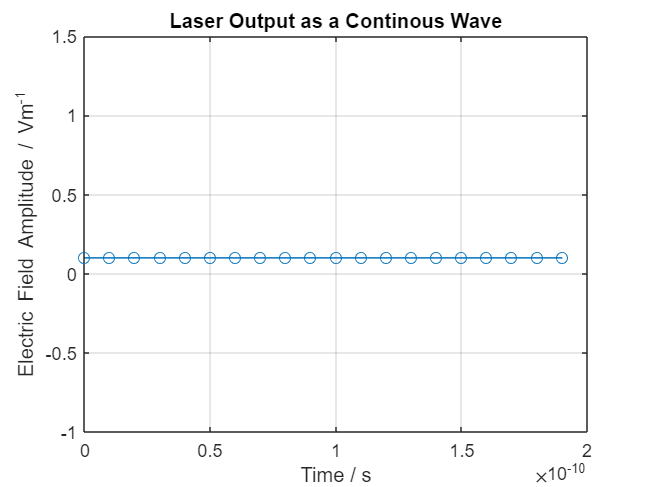

% Initialising laser parameters
lineWidth = 0;
laserPw_dBm = 10;
laserPw_Lin = 1e-3*10^(laserPw_dBm/10);

% Generating output from laser modelled as a contniuous-wave source
laserE = Laser(laserPw_dBm, lineWidth, SpS, Rs, NSymb, 1); % Laser output to be used with unshaped signals
laserE_shaped = Laser(laserPw_dBm, lineWidth, SpS, Rs, samples/SpS, 1); % Laser output to be used with shaped signals

% Visualising output from laser
t_interp = [0:0.25:NSymb*SpS - 1]*T;
plot(t(1:20), real(laserE(1:20)), "o-");
title("Laser Output as a Continous Wave");
xlabel("Time / s")
ylabel("Electric Field Amplitude / Vm^{-1}");
grid on

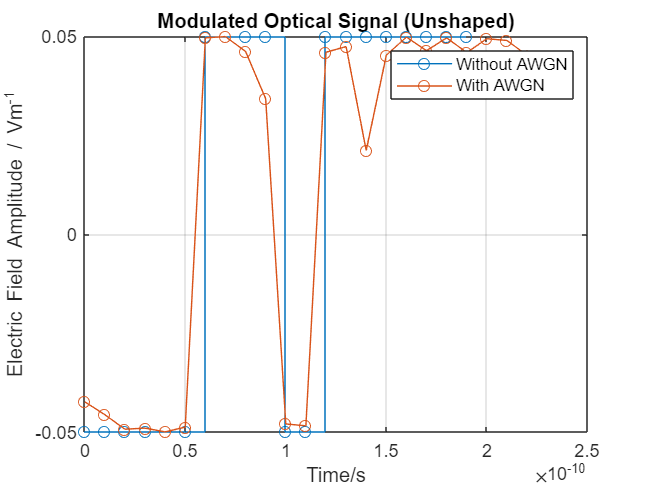


% Modulating optical signal using IQM
Vpi = pi/2; % Voltge required to change phase of E-field by pi
modOpticSig = IQModulatorModified(vIupsampled, vQupsampled, laserE, Vpi);
modOpticSig_AWGN = IQModulatorModified(real(vUpsampled_AWGN), imag(vUpsampled_AWGN), laserE, Vpi);
modOpticSig_shaped = IQModulatorModified(vI_shaped, vQ_shaped, laserE_shaped, Vpi);
modOpticSig_shaped_AWGN = IQModulatorModified(vI_shaped_AWGN, vQ_shaped_AWGN, laserE_shaped, Vpi);

% Visualising modulated optic signals
stairs(t(1:10*SpS), real(modOpticSig(1:10*SpS,11)), "o-");
hold on
plot(t(1:10*SpS+ filterSpan), real(modOpticSig_AWGN(1:10*SpS+ filterSpan, 11)), "o-");
title("Modulated Optical Signal (Unshaped)")
xlabel("Time/s")
ylabel("Electric Field Amplitude / Vm^{-1}")
legend("Without AWGN", "With AWGN")
grid on
hold off

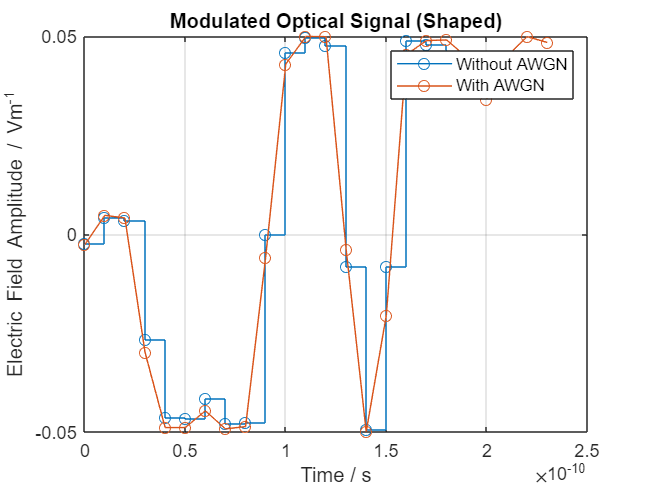


stairs(t(1:10*SpS), real(modOpticSig_shaped(1:10*SpS,11)), "o-");
hold on
plot(t(1:10*SpS+ filterSpan), real(modOpticSig_shaped_AWGN(1:10*SpS+ filterSpan, 11)), "o-");
title("Modulated Optical Signal (Shaped)")
xlabel("Time / s")
ylabel("Electric Field Amplitude / Vm^{-1}")
legend("Without AWGN", "With AWGN")
grid on
hold off

## Receiver

### Optical Front-End

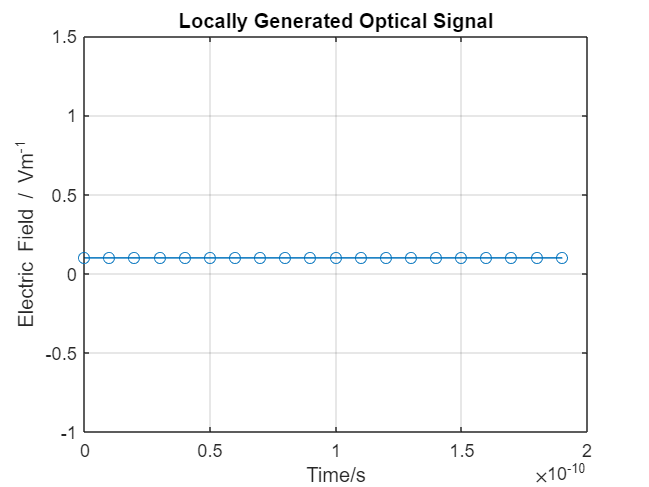

% Generating Local optical signal for coherent detection
Elo = laserE; % Identical to initial laser source
Elo_shaped = laserE_shaped;

% Visualising locally generated optical signal
plot(t(1:20), real(Elo(1:20,1)), "-o");
title("Locally Generated Optical Signal")
xlabel("Time/s")
ylabel("Electric Field / Vm^{-1}")
grid on

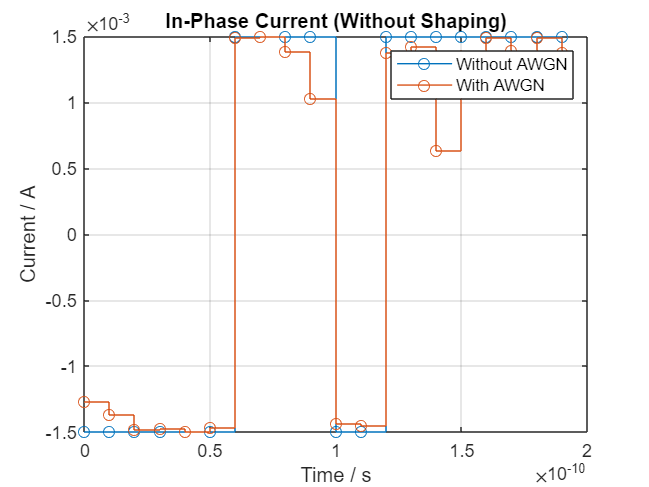


% Generating output from optical front-end
eta_ph = 0.3; % Responsivity of photodetectors

count = 1;

for i=1:size(modOpticSig,2)
    % Output from Optical Front-End
    OpticFEOut(:,count:count+1) = OpticalFrontEnd(modOpticSig(:,i), Elo, eta_ph, 1);
    OpticFEOut_AWGN(:,count:count+1) = OpticalFrontEnd(modOpticSig_AWGN(:,i), Elo, eta_ph, 1);
    OpticFEOut_shaped(:,count:count+1) = OpticalFrontEnd(modOpticSig_shaped(:,i), Elo_shaped, eta_ph, 1);
    OpticFEOut_shaped_AWGN(:,count:count+1) = OpticalFrontEnd(modOpticSig_shaped_AWGN(:,i), Elo_shaped, eta_ph, 1);
    count = count+2;
end

stairs(t(1:10*SpS), OpticFEOut(1:10*SpS,21), "-o"); % In-phase current
hold on
stairs(t(1:10*SpS), OpticFEOut_AWGN(1:10*SpS,21), "-o")
title("In-Phase Current (Without Shaping)")
xlabel("Time / s")
ylabel("Current / A")
legend("Without AWGN", "With AWGN")
grid on
hold off

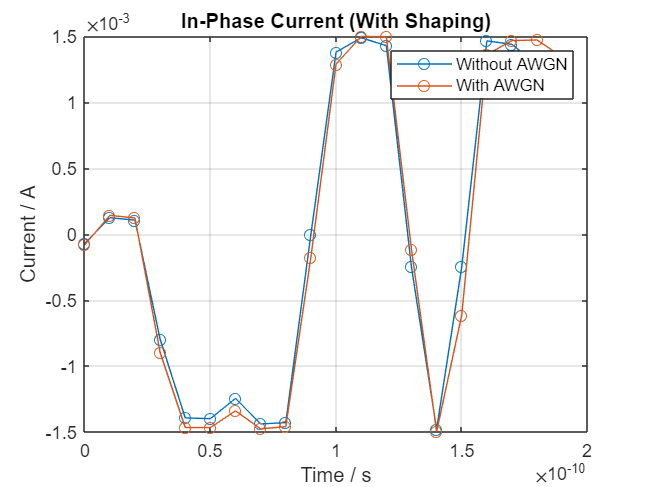


plot(t(1:10*SpS), OpticFEOut_shaped(1:10*SpS,21), "-o"); % In-phase current
hold on
plot(t(1:10*SpS), OpticFEOut_shaped_AWGN(1:10*SpS,21), "-o")
title("In-Phase Current (With Shaping)")
xlabel("Time / s")
ylabel("Current / A")
legend("Without AWGN", "With AWGN")
grid on
hold off

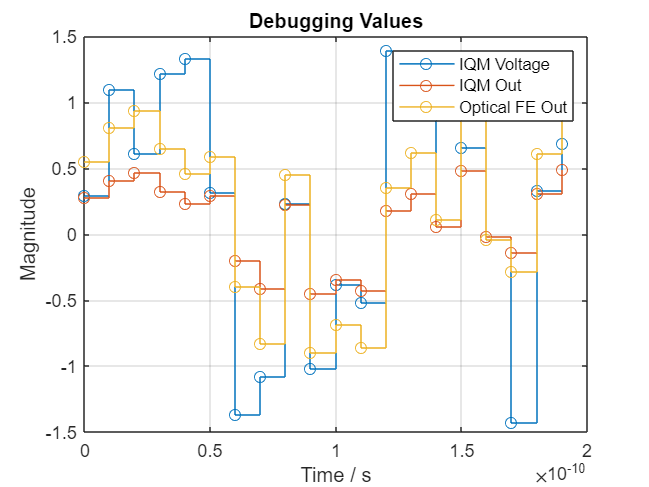


% TIA amplification and sampling using ADC
TIA_Gain = 1; % TIA amplification factor
Fs = SpS; % Sampling frequency of ADC
laserEMag = sqrt(laserPw_Lin);
scaleFactor = TIA_Gain*eta_ph*laserEMag*laserEMag/2;

% Amplification and separation of in-phase and quadrature components
OpticalFEOut_I = TIA_Gain*OpticFEOut(1:end, 1:2:end); OpticalFEOut_I_AWGN = TIA_Gain*OpticFEOut_AWGN(1:end, 1:2:end);
OpticalFEOut_Q = TIA_Gain*OpticFEOut(1:end, 2:2:end); OpticalFEOut_Q_AWGN = TIA_Gain*OpticFEOut_AWGN(1:end, 2:2:end);
OpticalFEOut_I_shaped = TIA_Gain*OpticFEOut_shaped(:, 1:2:end); OpticalFEOut_I_shaped_AWGN = TIA_Gain*OpticFEOut_shaped_AWGN(:, 1:2:end);
OpticalFEOut_Q_shaped = TIA_Gain*OpticFEOut_shaped(:, 2:2:end); OpticalFEOut_Q_shaped_AWGN = TIA_Gain*OpticFEOut_shaped_AWGN(:, 2:2:end);

% Comparing IQM values to Optical front-end output
stairs(t(1:10*SpS), real(vUpsampled_AWGN(1:10*SpS,1))/2, "-o");
hold on
stairs(t(1:10*SpS), 10*real(modOpticSig_AWGN(1:10*SpS,1)), "-o");
stairs(t(1:10*SpS), OpticalFEOut_I_AWGN(1:10*SpS,1)/scaleFactor, "-o");
title("Debugging Values");
xlabel("Time / s");
ylabel("Magnitude");
legend("IQM Voltage", "IQM Out", "Optical FE Out");  
grid on
hold off

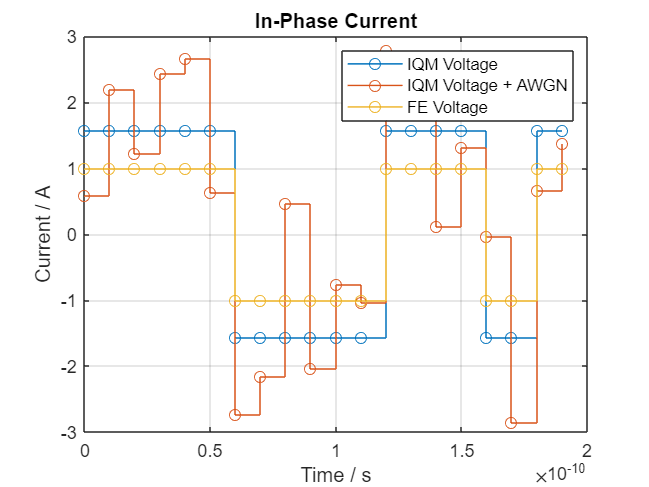


% Comparing voltages in IQM to those from the optical front-end output
stairs(t(1:10*SpS), vIupsampled(1:10*SpS,1), "-o");
hold on
stairs(t(1:10*SpS), real(vUpsampled_AWGN(1:10*SpS,1)), "-o");
stairs(t(1:10*SpS), OpticalFEOut_I(1:10*SpS,1)/scaleFactor, "-o");
title("In-Phase Current");
xlabel("Time / s");
ylabel("Current / A");
legend("IQM Voltage", "IQM Voltage + AWGN", "FE Voltage");  
grid on
hold off

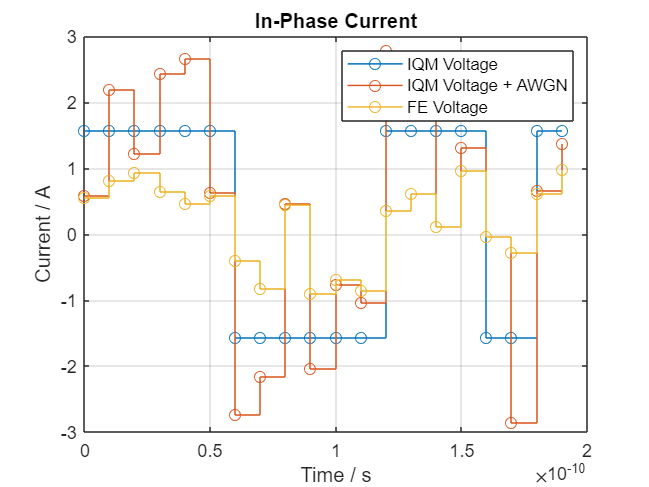


stairs(t(1:10*SpS), vIupsampled(1:10*SpS,1), "-o");
hold on
stairs(t(1:10*SpS), real(vUpsampled_AWGN(1:10*SpS,1)), "-o");
stairs(t(1:10*SpS), OpticFEOut_AWGN(1:10*SpS,1)/scaleFactor, "-o");
title("In-Phase Current");
xlabel("Time / s");
ylabel("Current / A");
legend("IQM Voltage", "IQM Voltage + AWGN", "FE Voltage");  
grid on
hold off

## DSP

% Downscaling and downsampling

% Scaling factor between output of IQM and output of optical front-end
laserEMag = sqrt(laserPw_Lin);
scaleFactor = TIA_Gain*eta_ph*laserEMag*laserEMag/2;

% Cancelling the scaling factor: 
% NOT Shaped
voltageI_scaled = OpticalFEOut_I/scaleFactor; voltageQ_scaled = OpticalFEOut_Q/scaleFactor; 
voltageI_AWGN_scaled = OpticalFEOut_I_AWGN/scaleFactor; voltageQ_AWGN_scaled = OpticalFEOut_Q_AWGN/scaleFactor; 
% Shaped
voltageI_shaped_scaled = OpticalFEOut_I_shaped/scaleFactor; voltageQ_shaped_scaled = OpticalFEOut_Q_shaped/scaleFactor; 
voltageI_shaped_AWGN_scaled = OpticalFEOut_I_shaped_AWGN/scaleFactor; voltageQ_shaped_AWGN_scaled = OpticalFEOut_Q_shaped_AWGN/scaleFactor; 

% Downsampling unshaped components
voltageI = voltageI_scaled(1:SpS:end, :); voltageQ = voltageQ_scaled(1:SpS:end, :);
voltageI_AWGN = voltageI_AWGN_scaled(1:SpS:end, :); voltageQ_AWGN = voltageQ_AWGN_scaled(1:SpS:end, :);

% Passing shaped components through matched filter and downsampling
voltageI_shaped = upfirdn(voltageI_shaped_scaled, filterResponse, 1, SpS); voltageI_shaped = voltageI_shaped(filterSpan + 1:end - filterSpan,:);
voltageQ_shaped = upfirdn(voltageQ_shaped_scaled, filterResponse, 1, SpS); voltageQ_shaped = voltageQ_shaped(filterSpan + 1:end - filterSpan,:);
voltageI_shaped_AWGN = upfirdn(voltageI_shaped_AWGN_scaled, filterResponse, 1, SpS); voltageI_shaped_AWGN = voltageI_shaped_AWGN(filterSpan + 1:end - filterSpan,:);
voltageQ_shaped_AWGN = upfirdn(voltageQ_shaped_AWGN_scaled, filterResponse, 1, SpS); voltageQ_shaped_AWGN = voltageQ_shaped_AWGN(filterSpan + 1:end - filterSpan,:);

### Decision

% Mapping scaled voltages to inital in-phase component of the symbol
% constellation.
% Quadrature component is ignored as it is the same value for all symbols.
% Maximum likelihood estimation, based on the Euclidian distance between the recieved voltage points
% and those corresponding to the symbols, is used.
decodedSymbols = ones(size(voltageI)); 
decodedSymbols(voltageI > 0) = 1; decodedSymbols(voltageI <= 0) = -1;
decodedInts = pskdemod(decodedSymbols, M);
decodedBits = int2bit(decodedInts, k);
biterr(decodedBits, sourceBits)

ans = 0


decodedSymbols_AWGN = ones(size(voltageI_AWGN));
decodedSymbols_AWGN(voltageI_AWGN > 0) = 1; decodedSymbols_AWGN(voltageI_AWGN <= 0) = -1;
decodedInts_AWGN = pskdemod(decodedSymbols_AWGN, M);
decodedBits_AWGN = int2bit(decodedInts_AWGN, k);

decodedSymbols_shaped = ones(size(voltageI_shaped));
decodedSymbols_shaped(voltageI_shaped > 0) = 1; decodedSymbols_shaped(voltageI_shaped <= 0) = -1;
decodedInts_shaped= pskdemod(decodedSymbols_shaped, M);
decodedBits_shaped = int2bit(decodedInts_shaped, k);
biterr(decodedBits_shaped, sourceBits)

ans = 0

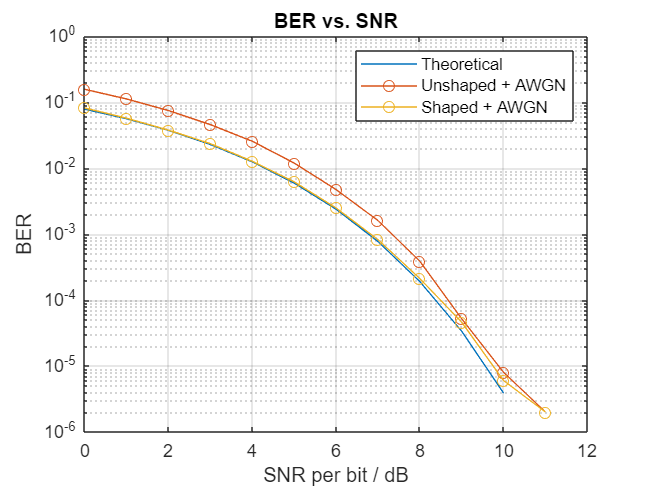


decodedSymbols_shaped_AWGN = ones(size(voltageI_shaped_AWGN));
decodedSymbols_shaped_AWGN(voltageI_shaped_AWGN > 0) = 1; decodedSymbols_shaped_AWGN(voltageI_shaped_AWGN <= 0) = -1;
decodedInts_shaped_AWGN= pskdemod(decodedSymbols_shaped_AWGN, M);
decodedBits_shaped_AWGN = int2bit(decodedInts_shaped_AWGN, k);

BER_BPSK_AWGN = zeros(NSequences,1); numErrors = zeros(NSequences,1);
BER_BPSK_AWGN_shaped = zeros(NSequences,1); numErrors_shaped = zeros(NSequences,1);

for i=1:NSequences
    [numErrors(i,1), BER_BPSK_AWGN(i,1)] = biterr(sourceBits(:,i), decodedBits_AWGN(:,i));
    [numErrors_shaped(i,1), BER_BPSK_AWGN_shaped(i,1)] = biterr(sourceBits(:,i), decodedBits_shaped_AWGN(:,i));
end

semilogy(SNRb_dB(1:11), 0.5*erfc(sqrt(10.^(SNRb_dB(1:11)/10))));
hold on
semilogy(SNRb_dB, BER_BPSK_AWGN, 'o-');
semilogy(SNRb_dB, BER_BPSK_AWGN_shaped, 'o-');
title("BER vs. SNR");
ylabel("BER");
xlabel("SNR per bit / dB");
legend("Theoretical", "Unshaped + AWGN", "Shaped + AWGN");
grid on
hold off


% save("BPSKData.mat","SNRb_dB", "BER_BPSK")